## Импорт данных


close all;
clear variables;

airRaw = readmatrix('data\air.txt');
breathRaw = readmatrix('data\breath.txt');
totalTime = readmatrix('data\totalTime.txt');

ttRaw = linspace(0, totalTime, length(airRaw))';


## Нормировка

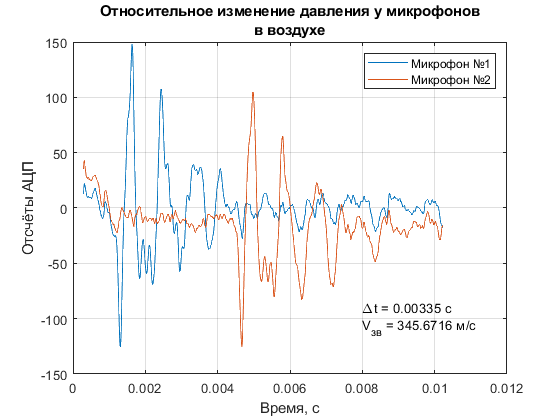


windowSize = 5;
b = (1 / windowSize) * ones(1, windowSize);
a = 1;

airFiltered = filter(b, a, airRaw());
breathFiltered = filter(b, a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
tt = ttRaw(start:end);

cAir = polyfit(tt, airFiltered(:, 1), 3);
cBreath = polyfit(tt, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, tt);
% airNorm = air ./ max(air);

breath = breathFiltered - polyval(cBreath, tt);
% breathNorm = breath ./ max(breath);


%% Расчёт скоростей

[u, airFirstPeakIndex] = max(air(:, 1));
[u, airSecondPeakIndex] = max(air(:, 2));

[u, breathFirstPeakIndex] = max(breath(:, 1));
[u, breathSecondPeakIndex] = max(breath(:, 2));

pipeLength = 1.158; % м

deltaTAir = tt(airSecondPeakIndex) - tt(airFirstPeakIndex);
deltaTBreath = tt(breathSecondPeakIndex) - tt(breathFirstPeakIndex);

speedInAir = pipeLength / deltaTAir;
speedInBreath = pipeLength / deltaTBreath;

f1 = figure();
plot(tt, air);
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе'});
legend('Микрофон №1', 'Микрофон №2');
xlabel('Время, с');
ylabel('Отсчёты АЦП');
text(0.008, -100, {['\Deltat = ' num2str(deltaTAir) ' c'], ['V_{зв} = ' num2str(speedInAir) ' м/с']});
saveas(f1, 'air.png');

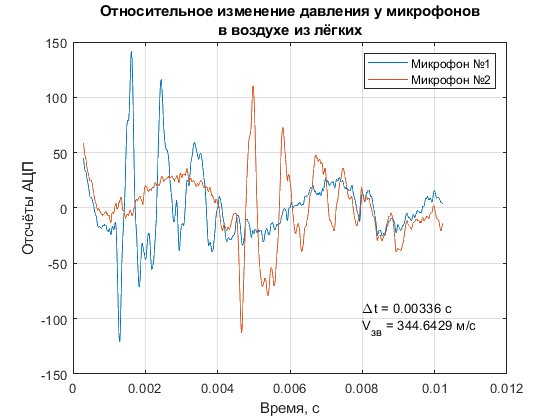


f2 = figure();
plot(tt, breath);
grid on;
title({'Относительное изменение давления у микрофонов', 'в воздухе из лёгких'});
legend('Микрофон №1', 'Микрофон №2');
xlabel('Время, с');
ylabel('Отсчёты АЦП');
text(0.008, -100, {['\Deltat = ' num2str(deltaTBreath) ' c'], ['V_{зв} = ' num2str(speedInBreath) ' м/с']});
saveas(f2, 'breath.png');

## График CO2

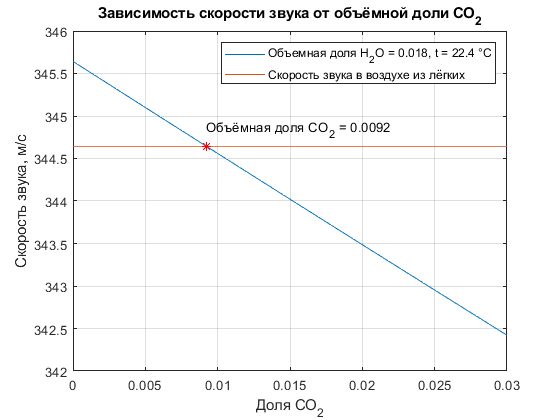

temperature = 22.4; % С
h2oX = 0.018;

T = 273.15 + temperature;
R = 8.314;

airMu = 28.97; % г/моль
airCp = 1.0036; % ?
airCv = 0.7166; % ?

h2oMu = 18.01; % г/моль
h2oCp = 1.863; % ?
h2oCv = 1.403; % ?

co2Mu = 44.01; % г/моль
co2Cp = 0.838; % ?
co2Cv = 0.649; % ?

co2X = linspace(0, 0.03, 100);
airX = 1 - h2oX - co2X;

Cp = airMu * airCp * airX + h2oMu * h2oCp * h2oX + co2Mu * co2Cp * co2X;
Cv= airMu * airCv * airX + h2oMu * h2oCv * h2oX + co2Mu * co2Cv * co2X;

gamma = Cp ./ Cv;
mu = airMu * airX + h2oMu * h2oX + co2Mu * co2X;

soundSpeed = sqrt(gamma * R * T ./ (mu / 1000));

co2XMeasured = 0.0092;

f3 = figure();
plot(co2X, soundSpeed);
hold on;
plot(co2X, speedInBreath * ones(size(co2X)));
plot(co2XMeasured, speedInBreath, 'r*');
text(co2XMeasured, speedInBreath + 0.2, 'Объёмная доля CO_2 = 0.0092');
grid on;
legend('Объемная доля H_2O = 0.018, t = 22.4 °C', 'Скорость звука в воздухе из лёгких');
xlabel('Доля CO_2');
ylabel('Скорость звука, м/с');
title('Зависимость скорости звука от объёмной доли CO_2');
saveas(f3, 'result.png');